## Example script for performing Fourier Transforms

First to load an example file (only run this bit once)

addpath(genpath("../../"));

load("C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s01_ex01_s01.mat");

Then to actually perform computations

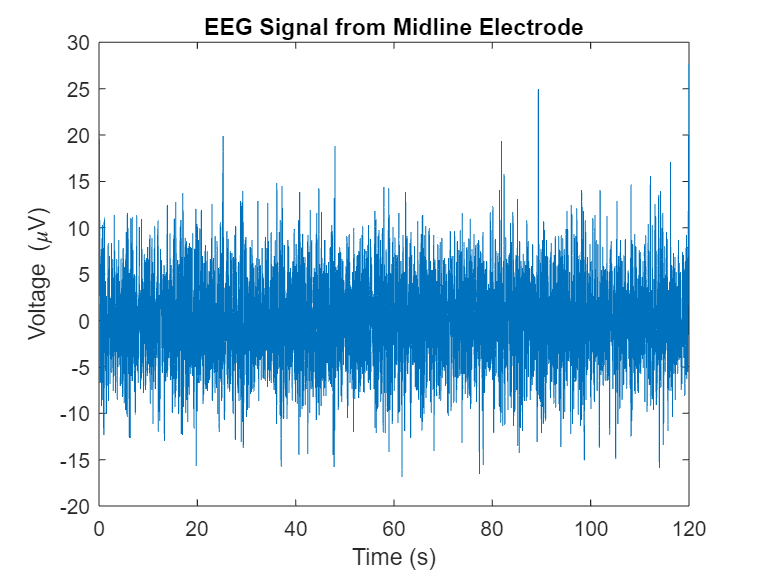

fs = 200;   % Sampling Frequency (Hz)
L = 120;    % Length of signal (ms)
T = 1/fs;   % Period
t = 0:T:L;  % Time vector

fig = figure;

plot(t(1:end - 1), Cz); % Plotting midline electrode readings against time
title("EEG Signal from Midline Electrode");
xlabel("Time (s)");
ylabel("Voltage (\muV)");

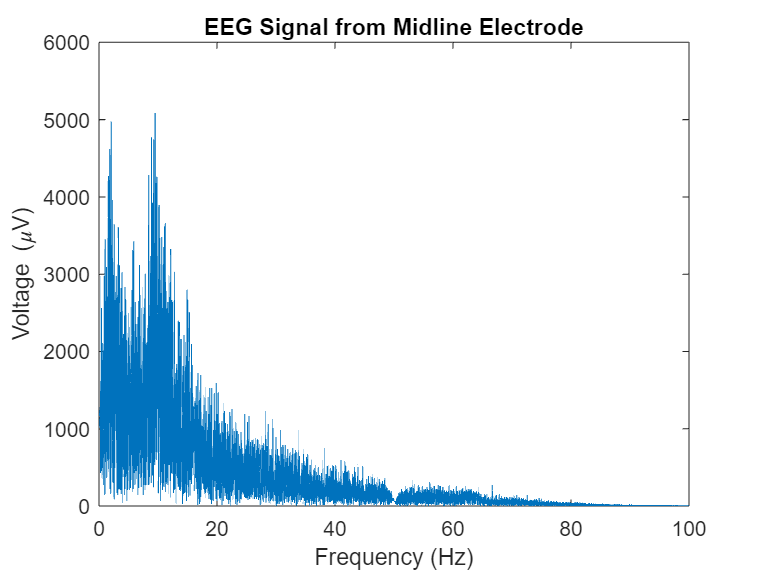


fig2 = figure;
transformed_Cz = fft(Cz);                           % Performing transform
transformed_Cz = abs(transformed_Cz(1:(L*fs/2)));   % Throwing away second half and taking absolute value
f = (0:(L * fs)/2 - 1) / L;                         % Creating frequency vector

plot(f, transformed_Cz); % Plotting the transform in the Frequency domain
title("EEG Signal from Midline Electrode");
xlabel("Frequency (Hz)");
ylabel("Voltage (\muV)");

References:

(More useful) [https://personal.utdallas.edu/~dlm/3350%20comm%20sys/FFTandMatLab-wanjun%20huang.pdf](https://personal.utdallas.edu/~dlm/3350%20comm%20sys/FFTandMatLab-wanjun%20huang.pdf)

(Less useful) [https://www.mathworks.com/help/matlab/ref/fft.html](https://www.mathworks.com/help/matlab/ref/fft.html)